clc; clear all; close all;
dr=[0;(0.24*pi)/(((2).^0.5));0]

dr =          0
    0.5331
         0


dv=[0.03;0.01;-0.02]

dv =     0.0300
    0.0100
   -0.0200


ns=(2^0.5)/4    

ns = 0.3536

t=[(-5:18)];


psi=ns*t;
for i=1:length(t)

    Phirr(:,:,i)=[(4-3*cos(psi(i))),0,0;
        6*(sin(psi(i))-(psi(i))),1,0;
        0,0,cos(psi(i))];

    Phirv(:,:,i)=[sin(psi(i))/ns,(2-2.*cos(psi(i)))/ns,0;
        (2*cos(psi(i)-1))/ns,(4*sin(psi(i)))/ns-(3*(psi(i)))/ns,0;
        0,0,sin(psi(i))/ns];
    Dr(:,:,i)=(Phirr(:,:,i)*dr)+(Phirv(:,:,i)*dv); 

    Phivr(:,:,i)=[3*ns*sin(psi(i)),0,0;
        6*ns*(cos(psi(i))-1),0,0;
        0,0,-(ns*sin(psi(i)))];

    Phivv(:,:,i)=[cos(psi(i)),2*sin(psi(i)),0;
        -2*sin(psi(i)),4*cos(psi(i))-3,0;
        0,0,cos(psi(i))];
    
    Dv(:,:,i)=(Phivr(:,:,i)*dr)+(Phivv(:,:,i)*dv);
end
    
 

%Phirv=[((1./ns).*(sin(psi))),(2./ns).*(1-cos(psi)),0;(2./ns).*(cos(psi)-1),((4./ns).*(sin(psi)))-((3./ns).*(psi)),0;0,0,(1./ns).*(sin(psi))]

Dr1(:,1)=Dr(1,:,:);
Dr2(:,1)=Dr(2,:,:);
Dr3(:,1)=Dr(3,:,:);
DRR=(Dr1.^2+Dr2.^2+Dr3.^2).^0.5

DRR =     0.4182
    0.4199
    0.4496
    0.4997
    0.5615
    0.6248
    0.6789
    0.7134
    0.7204
    0.6951



Dv1(:,1)=Dv(1,:,:);
Dv2(:,1)=Dv(2,:,:);
Dv3(:,1)=Dv(3,:,:);
DVV=(Dv1.^2+Dv2.^2+Dv3.^2).^0.5

DVV =     0.0333
    0.0387
    0.0431
    0.0433
    0.0400
    0.0374
    0.0419
    0.0548
    0.0712
    0.0866


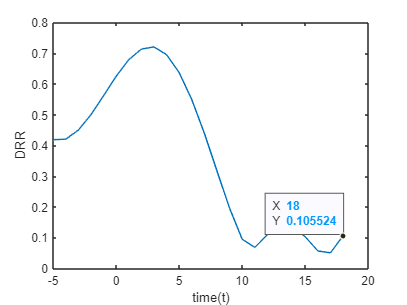


plot(t,DRR)
xlabel('time(t)')
ylabel('DRR')

ax = gca;
chart = ax.Children(1);
datatip(chart,17.77,0.0706);